# Illustrate Poisson Distribution of Electrons

The Poisson nature of the sensor absorptions, for a noise-free camera.

We create a uniform scene with a small field of view.  We then image this onto the center of a small sensor (monochrome).  We plot the number of electrons for different exposure durations.

In the last section, we turn on the sensor noise.  This illustrates the relative size of the Photon noise and Sensor noise for this particular case.

ieInit

### Build the scene, oi, and sensor.  

scene = sceneCreate('uniform');
scene = sceneSet(scene,'fov',2);    % Small field of view
oi = oiCreate;
oi = oiCompute(oi,scene);

### Build a sensor

sensor = sensorCreate('monochrome');
sensor = sensorSetSizeToFOV(sensor,1.5,oi);
sensor = sensorSet(sensor,'noise flag',1);  % Only photon noise

### Calculate sensor response using relatively long (10 ms) exposure

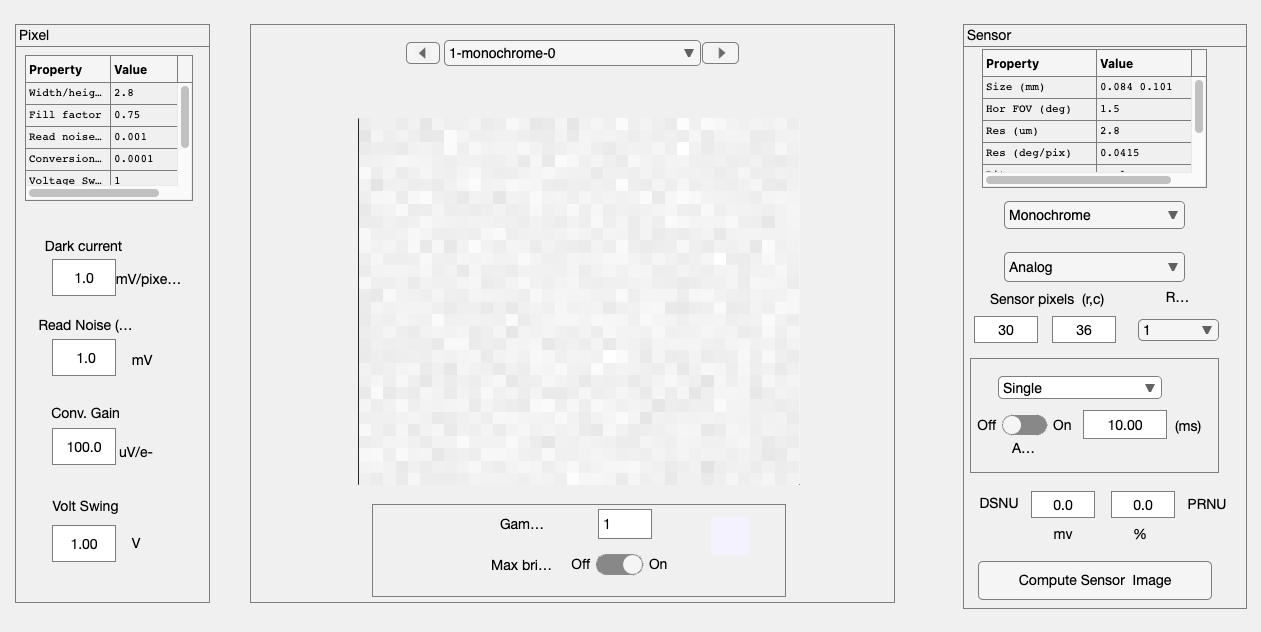

longE = 1e-2;
sensor = sensorSet(sensor,'exp time',longE); 
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

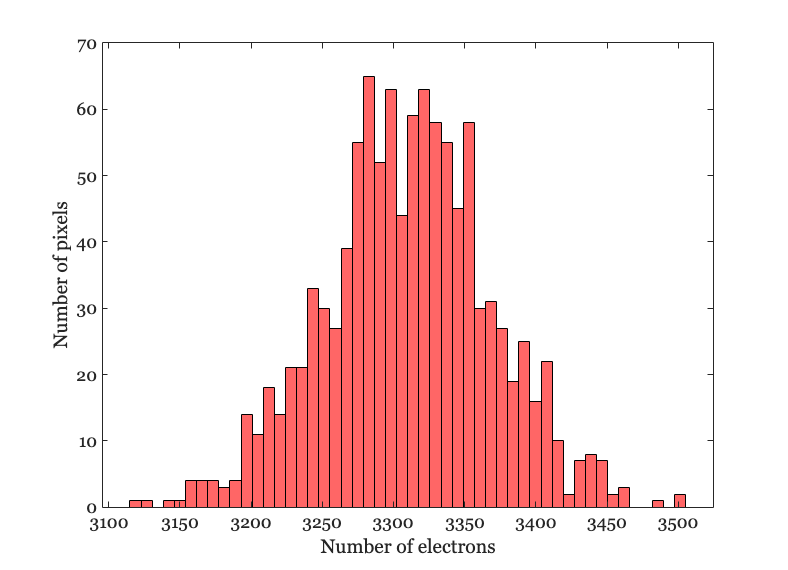

ieNewGraphWin;
e = sensorGet(sensor,'electrons');
histogram(e(:),50);
xlabel('Number of electrons');
ylabel('Number of pixels');

### Shorten the exposure duration by 1000 to 15 microseconds

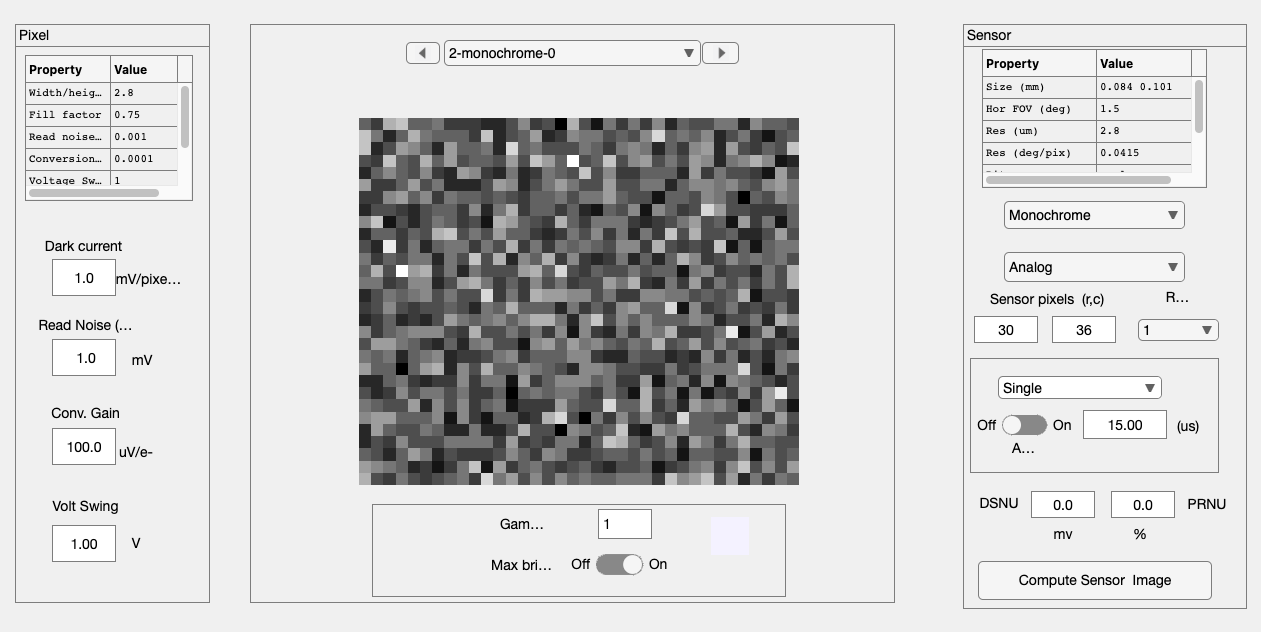

shortE = 1.5e-5;
sensor = sensorSet(sensor,'exposure time',shortE);
sensor = sensorCompute(sensor,oi);
e = sensorGet(sensor,'electrons');
sensorWindow(sensor);

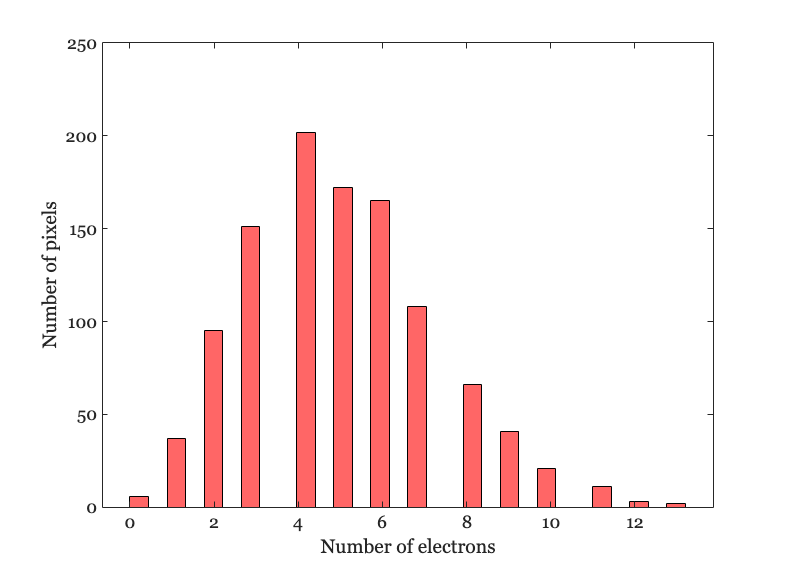

ieNewGraphWin;
histogram(e(:),30);
xlabel('Number of electrons');
ylabel('Number of pixels');

### Turn on sensor noise; compute for combined sensor and photon noise

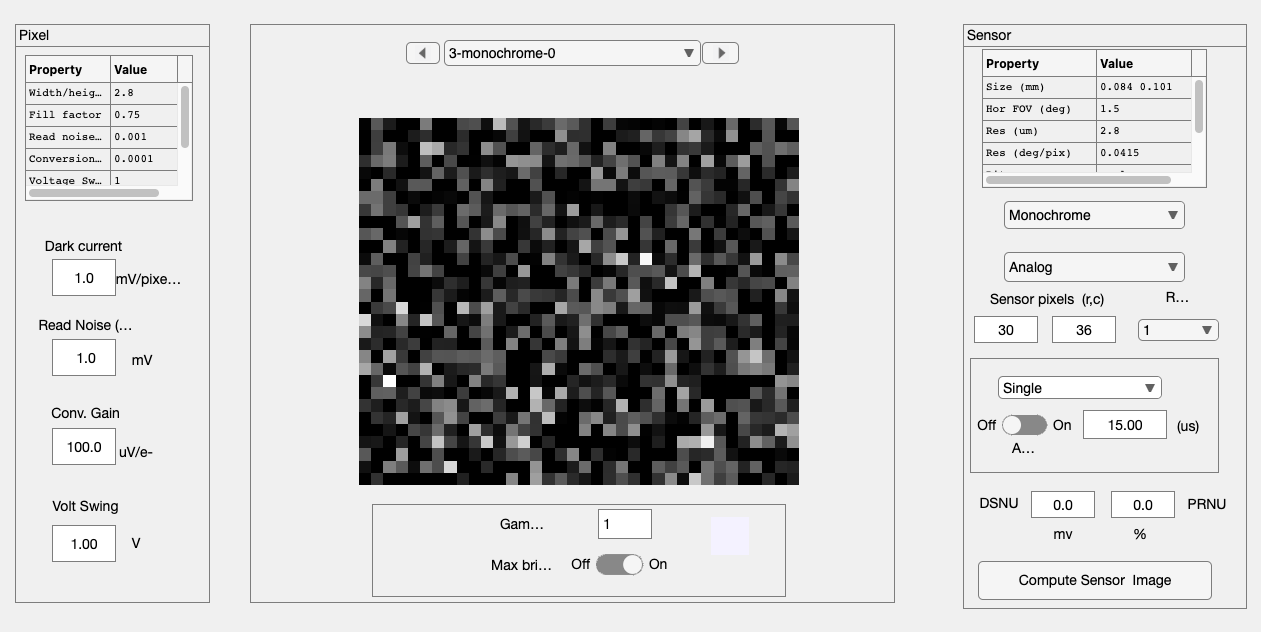

sensor = sensorSet(sensor,'noise flag',2); 
sensor = sensorCompute(sensor,oi);
e = sensorGet(sensor,'electrons');
sensorWindow(sensor);

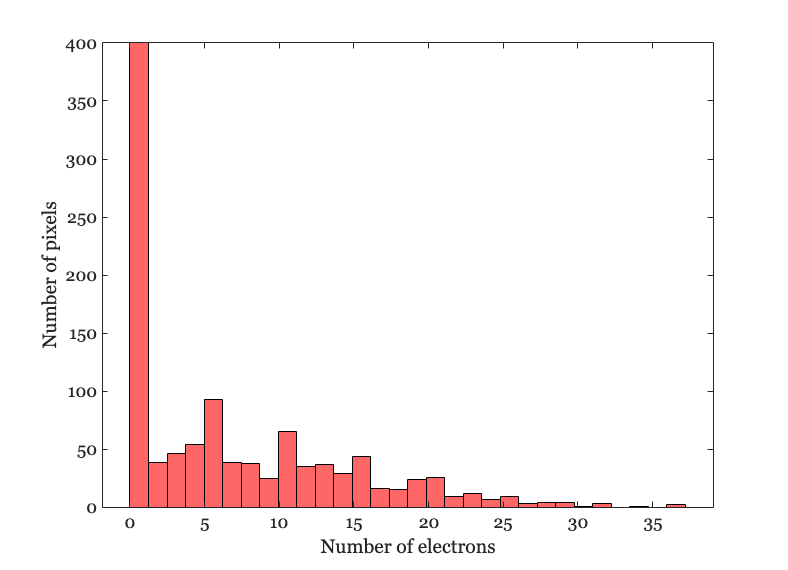

ieNewGraphWin; 
histogram(e(:),30);
xlabel('Number of electrons');
ylabel('Number of pixels');